## **IMU Simulation To Test Madgwick Filter Implementation**

Generate N samples at sample rate of Fs

N = 1000;
Fs = 512;

Generate time and ideal datapoints

time = (0:(1/Fs):((N-1)/Fs))';
accelIdeal = zeros(N, 3);
gyroIdeal = zeros(N, 3);
magIdeal = zeros(N, 3);

% apply test system model
for i = 1:N
    
    % sinusoidal angular velocity readings
    %gyroIdeal(i,1) = 10*sin(i/20); % filter converges away from true state
    
    gyroIdeal(i,1) = i/10;
    gyroIdeal(i,2) = i/20;
    gyroIdeal(i,3) = 2;
end

Configure IMU model

% default sensor parameters
params_gyr = gyroparams;
params_acc = accelparams;
params_mag = magparams;

% TODO: tweak IMU config

imu = imuSensor('IMUType', 'accel-gyro-mag', 'SampleRate', Fs, 'Gyroscope', params_gyr, 'Accelerometer', params_acc, 'Magnetometer', params_mag);

% get IMU measurements
[accelMeasure, gyroMeasure, magMeasure] = imu(accelIdeal, gyroIdeal);

magMeasure = zeros(N,3); % TEMP

Initialize Madgwick filter

updateFreq = 512;
beta = 0.1;
zeta = 0;

% starting orientation quaternion
qReal = [1 0 0 0];

madgwick = Madgwick('Quaternion', qReal, 'UpdateFrequency', updateFreq, 'Beta', beta, 'Zeta', zeta);

Determine real versus estimated orientation quaternions

orientationReal = zeros(N, 4);
orientationEst = zeros(N, 4);

for i = 1:N
    
    % Compute real orientation quaternion:
    
    q = qReal;
    gyro = [0 gyroIdeal(i,:)];
    
    % angular rate quaternion
    qDot = 0.5 * [q(1)*gyro(1) - q(2)*gyro(2) - q(3)*gyro(3) - q(4)*gyro(4);
                  q(1)*gyro(2) + q(2)*gyro(1) + q(3)*gyro(4) - q(4)*gyro(3);
                  q(1)*gyro(3) - q(2)*gyro(4) + q(3)*gyro(1) + q(4)*gyro(2);
                  q(1)*gyro(4) + q(2)*gyro(3) - q(3)*gyro(2) + q(4)*gyro(1)]';
    
    % integrate rate of change and add to current quaternion
    qReal = qReal + qDot / updateFreq;
    qReal = qReal / norm(qReal);

    % Obtain estimated orientation quaternion:
    madgwick.update(gyroMeasure(i,:), accelMeasure(i,:), magMeasure(i,:));
    
    % store datapoints
    orientationReal(i, :) = qReal;
    orientationEst(i, :) = madgwick.qEst;
end

Visualize data

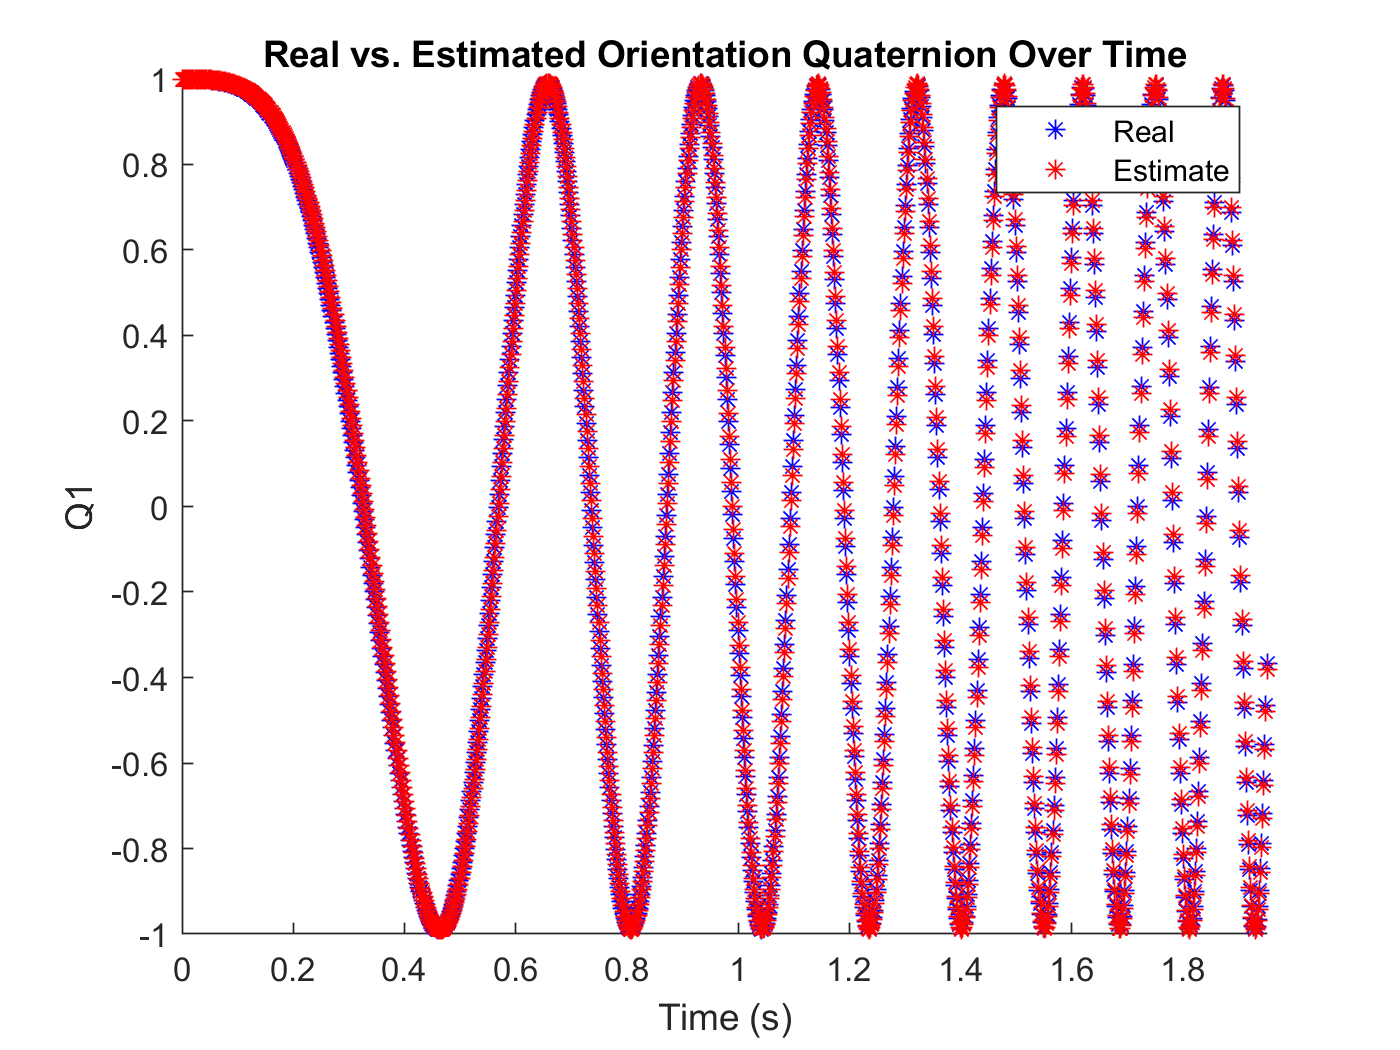

%q1
figure
hold on
plot(time, orientationReal(:,1), '*', 'Color', 'b')
plot(time, orientationEst(:,1), '*', 'Color', 'r')
title('Real vs. Estimated Orientation Quaternion Over Time')
xlabel('Time (s)')
ylabel('Q1')
xlim([0,time(end)])
legend('Real', 'Estimate')

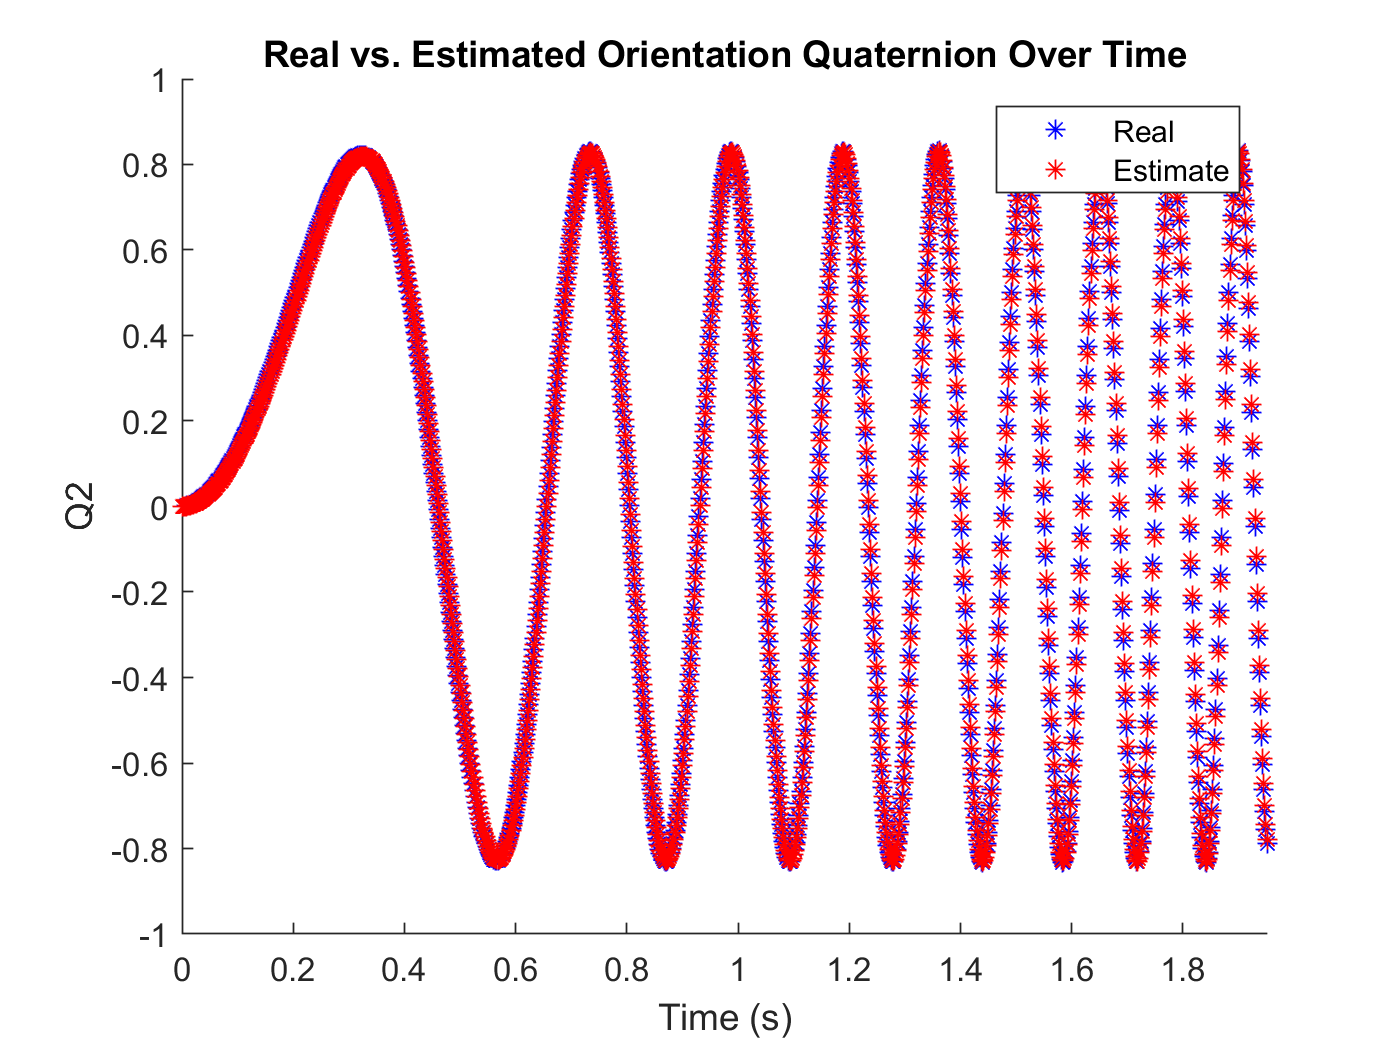


%q2
figure
hold on
plot(time, orientationReal(:,2), '*', 'Color', 'b')
plot(time, orientationEst(:,2), '*', 'Color', 'r')
title('Real vs. Estimated Orientation Quaternion Over Time')
xlabel('Time (s)')
ylabel('Q2')
xlim([0,time(end)])
legend('Real', 'Estimate')

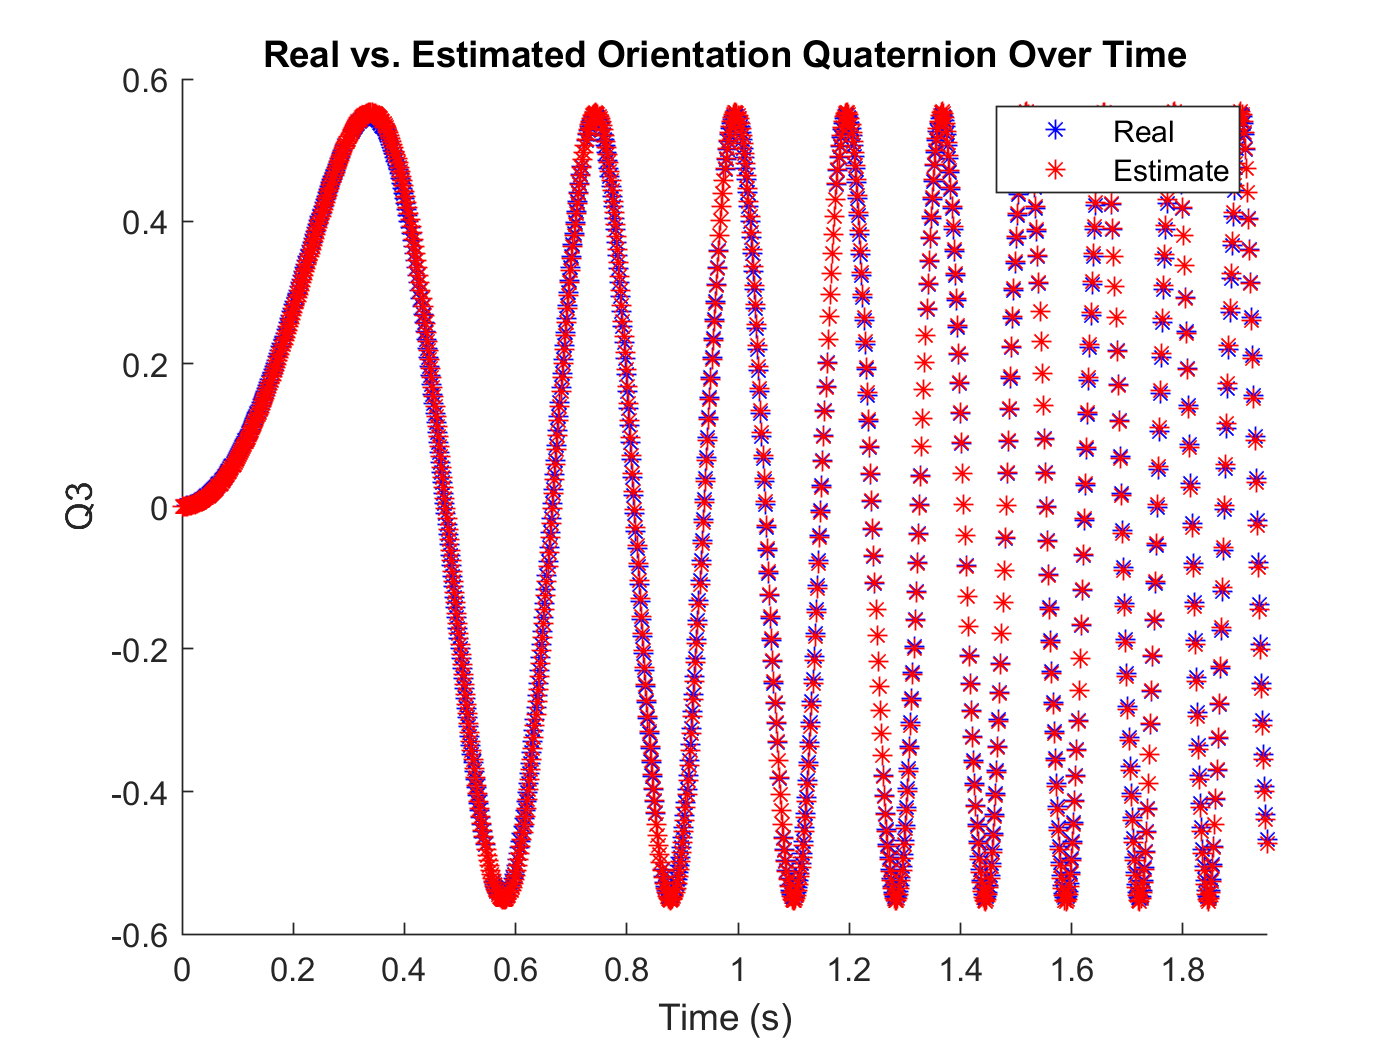


%q3
figure
hold on
plot(time, orientationReal(:,3), '*', 'Color', 'b')
plot(time, orientationEst(:,3), '*', 'Color', 'r')
title('Real vs. Estimated Orientation Quaternion Over Time')
xlabel('Time (s)')
ylabel('Q3')
xlim([0,time(end)])
legend('Real', 'Estimate')

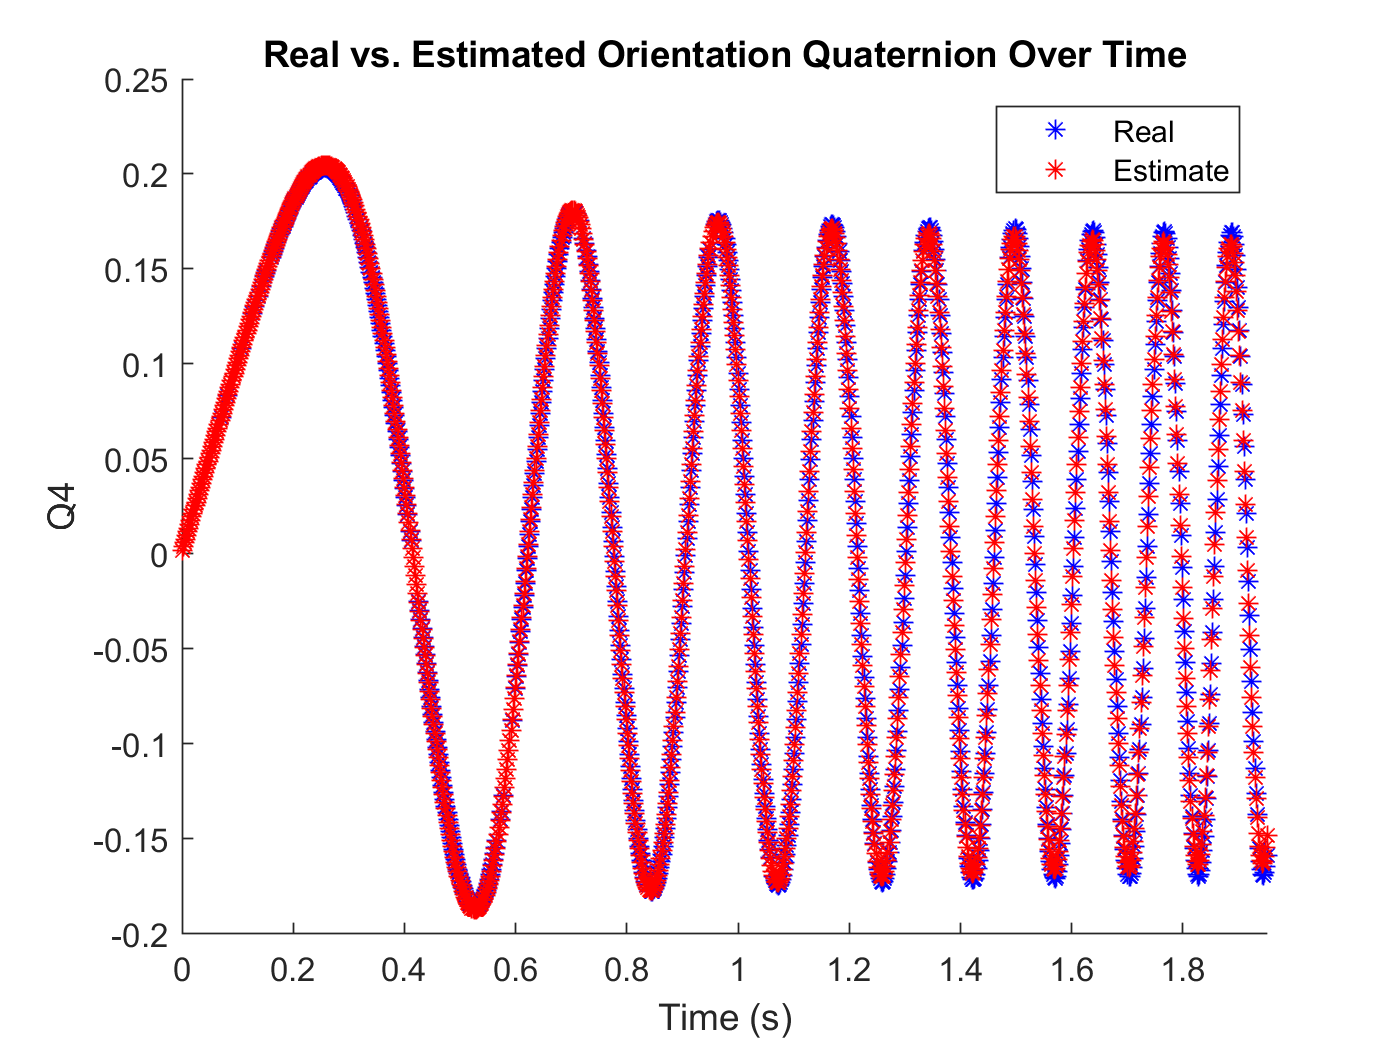


%q4
figure
hold on
plot(time, orientationReal(:,4), '*', 'Color', 'b')
plot(time, orientationEst(:,4), '*', 'Color', 'r')
title('Real vs. Estimated Orientation Quaternion Over Time')
xlabel('Time (s)')
ylabel('Q4')
xlim([0,time(end)])
legend('Real', 'Estimate')